# MATLAB® による宇宙のデータを用いたデータ解析入門

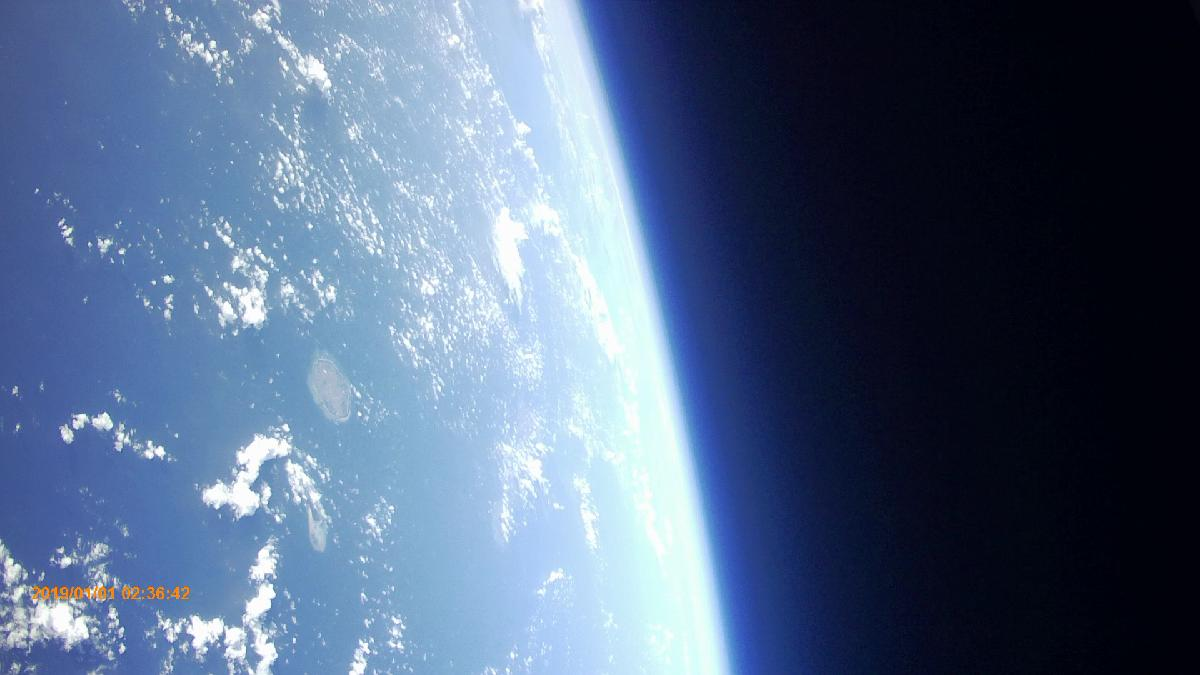

## e-kagakuアカデミー　×　MathWorks®

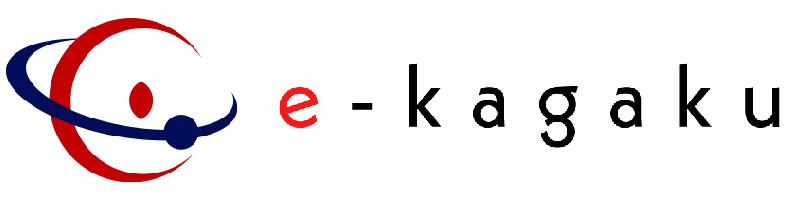　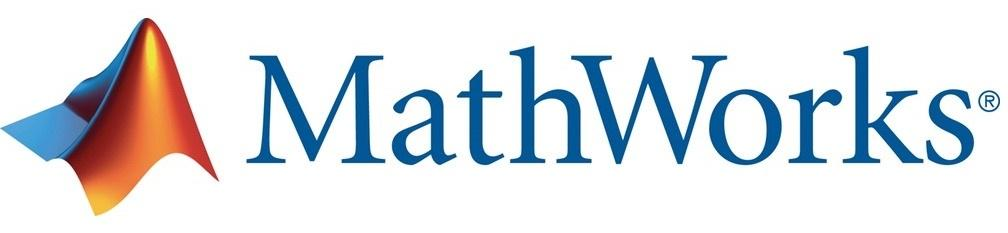

## **Mission3 (Advanced) もっと解析しよう**

宇宙のデータをさらに詳しく解析して研究発表してみましょう．解析の仕方によっては新たな発見をすることができるかもしれません．ここでは，より深くデータについて考察するために必要なスキルを身に着けていきます．

まずは，Mission2 で確認した，高度に対する温度変化について，分析していきます．高度と温度変化データに関する分析方法のイメージがついたら，次は自分で好きなデータについて解析してみましょう！

### データの取り込み

まずは，このセクションを実行し，分析に必要な変数をベースワークスペースに定義しましょう．

load mission3_data.mat

参考までに，上記の処理について説明します．

ここで登場するのは，`load`** 関数**と，"mission3_data.mat" という **MAT-ファイル**です．

**MAT-ファイル**は，ファイルからデータをインポートした変数や，プログラムで作成された変数を保存することができるファイルです．"mission3_data.mat" は，Mission3 で使用する変数を保存しています．

`load`** 関数**は，MAT-ファイルにある変数をインポートする関数です．

インポートが終わると，ワークスペースに，以下 4 つの変数が取り込まれます．これらの変数には，上昇開始から高度 10000m に達するまでのデータを保存しています．

- `t_m3         `: 時刻

- `height_m3    `: 高度

- `temp_m3`             : 気温

- `grad_temp_m3 `: 各時刻における，高度に対する気温変化率

これらの変数は，次以降のセクションで使用します．

### データの可視化と直線近似

まずは，下記のヒントを参考に，高度と気温のデータを散布図でグラフ化してみましょう．さらに近似直線を引いてみましょう．

**ヒント）散布図と近似直線**

scatter(height_m3, temp_m3)
p = polyfit(height_m3,temp_m3,1)

p =    -0.0044   28.1633


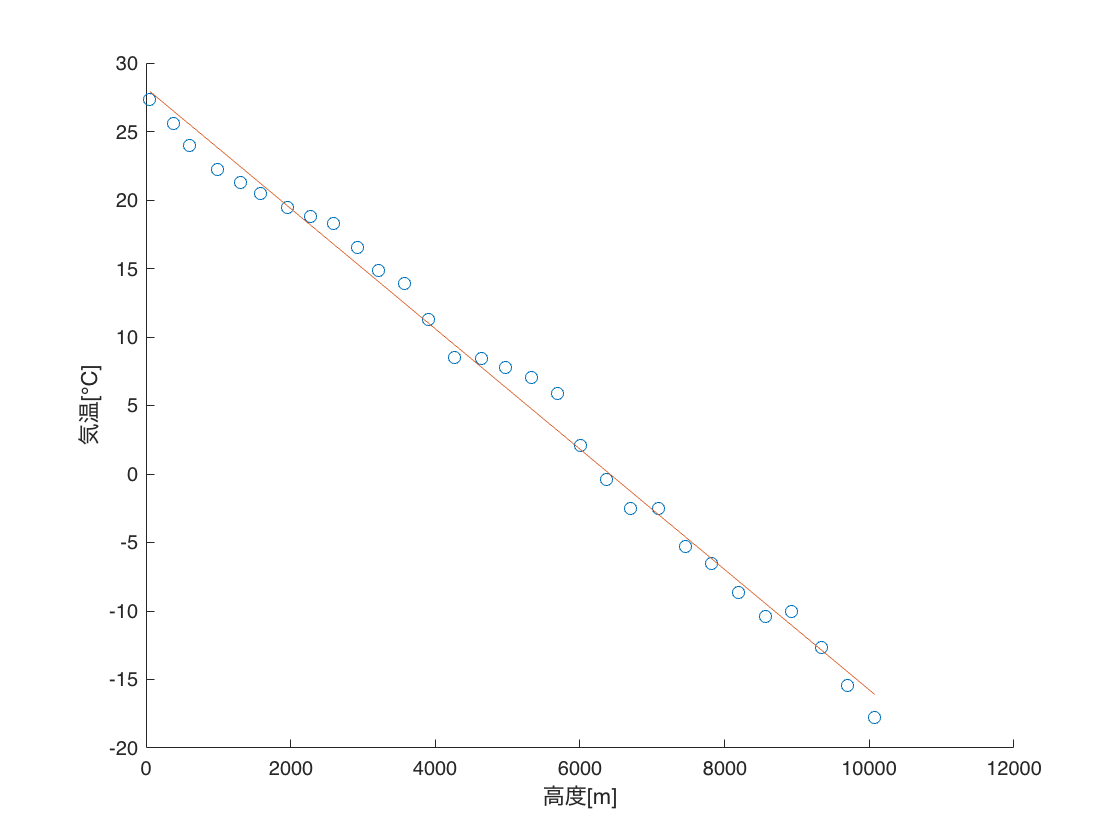

xlabel('高度[m]')
ylabel('気温[℃]')
temp_m3_subs = polyval(p,height_m3);
hold on
plot(height_m3,temp_m3_subs)
hold off

散布図のデータは，近似直線上にありますか？それとも近似直線から少しずれていますか？

### データの相関

上記のグラフは，直線上に分布しているように見えますね．次に，高度データと気温データの相関を調べてみましょう．

**ヒント）相関係数**

corr_rise = corr2(height_m3, temp_m3) 

corr_rise = -0.9961

相関係数の値はいくつになりましたか？相関係数の値から，高度と気温の関係性について，どのようなことが言えそうですか？

### 気温の変化率の散布図

次に，気温の変化率について，平均・分散を求めていきます．まずは，データの特徴を見るために，気温の変化率を散布図でグラフ化してみましょう．（縦軸の範囲は -0.05 から 0.05 にすると見やすいです．）

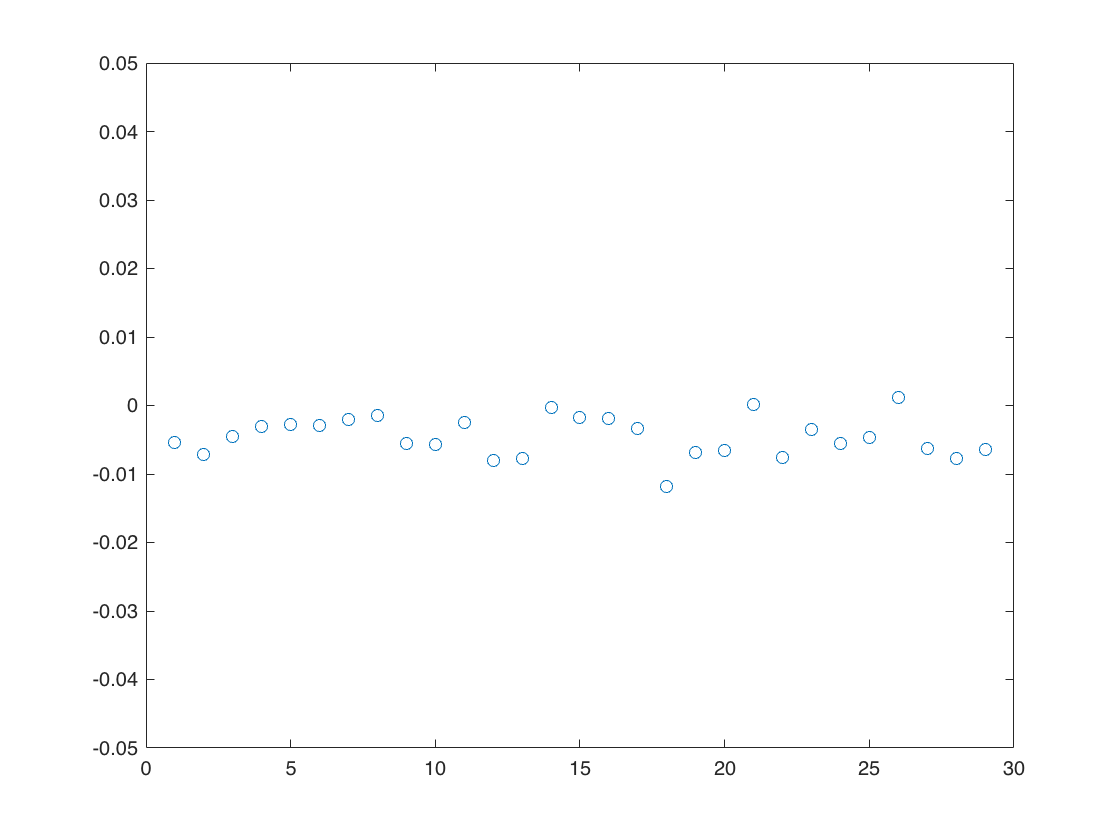

plot(grad_temp_m3,'o')
ylim([-5e-2 5e-2]) % 縦軸の範囲は -0.05 から 0.05 に設定

グラフから，少しばらつきがあるのが確認できますね．

今回，高度に対する気温の変化率は予め用意しました．変化率の求め方を知りたい人は，下記 ヒント を見てみましょう．

**ヒント）気温の変化率の求め方**

### 平均，分散と標準偏差

それでは，実際に，平均・分散・標準偏差を求めてみましょう．平均・分散を求めることで，新たに分かったこと，またはこれまで解析してきたことを裏付けられますか？

**ヒント）平均と分散**

% 平均
grad_temp_ave = mean(grad_temp_m3)  % 平均

grad_temp_ave = -0.0046

% 分散
grad_temp_var = var(grad_temp_m3,1) % 分散

grad_temp_var = 8.2010e-06

% 標準偏差
grad_temp_std = std(grad_temp_m3,1) % 標準偏差

grad_temp_std = 0.0029

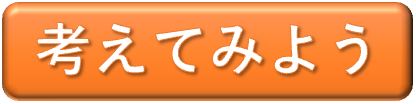

平均値は，先ほど求めた直線近似の結果と比べて，大きいですか？それとも小さいですか？

どうしてそのような結果になったと思いますか？

また，分散や標準偏差の結果から，どのようなことが言えそうですか？

### 標準偏差の意味

統計を勉強する時に，”標準偏差” という言葉を聞くこともあるかと思いますが，これはどのような意味があるのでしょうか？

まずは，高度に対する気温の変化率のデータに対し，平均値と，平均値 ± 標準偏差 の線を引いてみましょう．

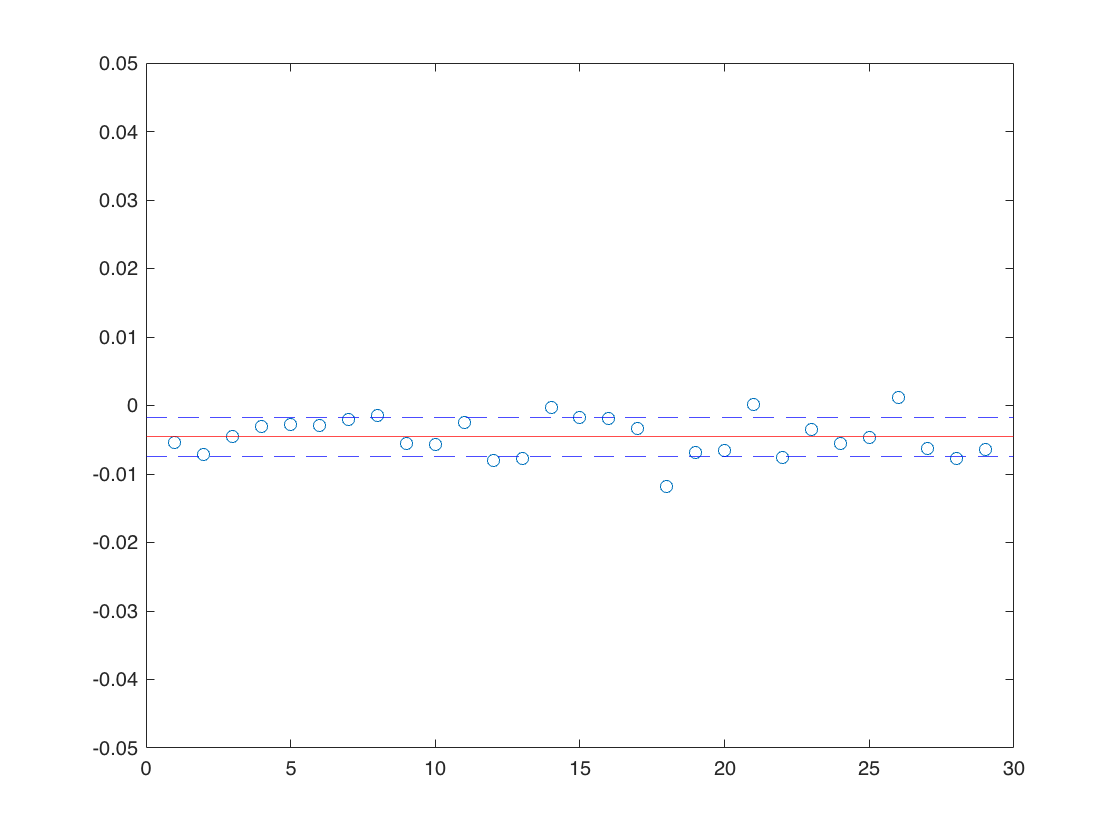

plot(grad_temp_m3,'o')
ylim([-5e-2 5e-2])

yline(grad_temp_ave,'r')
yline(grad_temp_ave + grad_temp_std,'b--')
yline(grad_temp_ave - grad_temp_std,'b--')

グラフで見るとイメージがつくかと思いますが，データに対し，**約70%**のデータが **平均値 ± 標準偏差** の間に含まれます．

つまり，標準偏差が小さいほど，青い点線の距離が小さくなり，バラツキが少ないデータであることが分かります．

### 最小二乗法と平均値，どちらの結果を利用すると良い？

Mission3 では，以下の2通りについて，気温の変化率を求めました．

- 高度と気温のデータに対して，最小二乗法で誤差が最小となる傾きを求める

- 隣り合うデータから気温の変化率を求め，平均を計算

今回の場合，どちらで求めるのが良いでしょうか？

考え方は色々あると思います．私たちは，今回，1番の方法が良いという結論を出しました．

その理由としては，気温の変化率を求めるには，すべてのデータを考慮して求めることが最善と考えたからです．

平均値の場合，隣り合うデータの変化率を求めているため，すべてのデータを考慮しているとは言いづらいです．

ただし，最小二乗法で求める場合，データに外れ値があると本来の結果からずれてしまうこともあるので，データ全体を俯瞰して，本来あるはずがないデータがないか，解析前にしっかり確認する必要があります．

これでミッションはおわりです．

[**おわりに**](matlab:edit("sbda_mission4final.mlx"))

Copyright 2020 - 2022 The MathWorks, Inc.